# ECM307-G01T02L03D - Atividade T3

%% Atividade T3 - Análise de Vogais
%% Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas

## baixando arquivo de voz e plotando gráficos

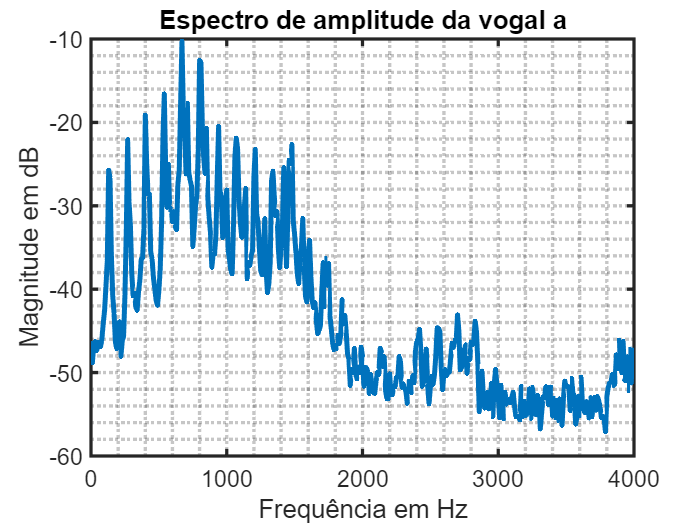

load("Voz.mat")
figure(1)
plot(frequencia,Y0)
title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor

%%% modifica parâmteros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

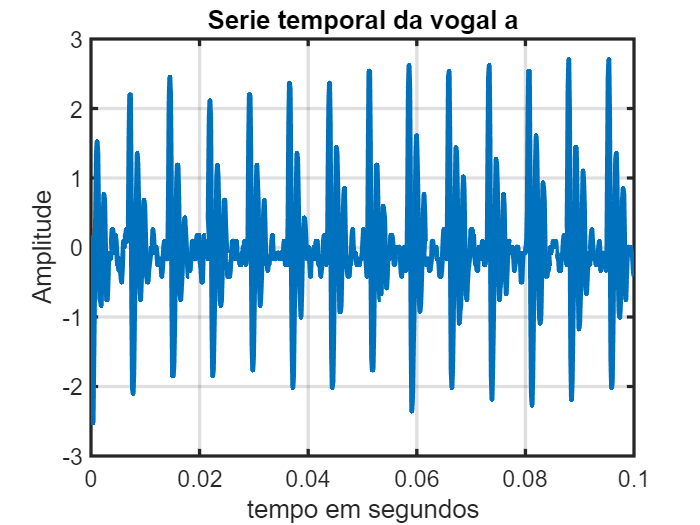



figure(2)
plot(t,Vp)
xlabel('tempo em segundos')
ylabel('Amplitude')
title('Serie temporal da vogal a')
grid;

%%% modificando parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

## calculando amostragem

fs = length(Vp)/0.1

fs = 8000

Ts = 1/fs

Ts = 1.2500e-04

## Laplace

% achar sigma e omega de laplace


$$\begin{array}{l}
s=\sigma +j\omega \to e^{-\left(\sigma +j\omega \;\right)} \to e^{-\sigma \;t} e^{-j\omega t} \\
e^{-\sigma } e^{-j\omega t} \\
e^{-\sigma t} \left(\cos \left(\omega t\right)+\mathrm{jsin}\left(\omega t\right)\right)+\\
e^{-\sigma t} \left(\cos \left(\omega t\right)-\mathrm{jsin}\left(\omega t\right)\right)=\\
2e^{-\sigma t} \cos \left(\omega t\right)
\end{array}$$


ti = 0.00112641;        % periodo inicial
t_f = 0.0953692;        % periodo final
T = (t_f - ti)/13;       % 13 = número de periodos
f = 1/T;
w = 2*pi*f

w = 866.7126

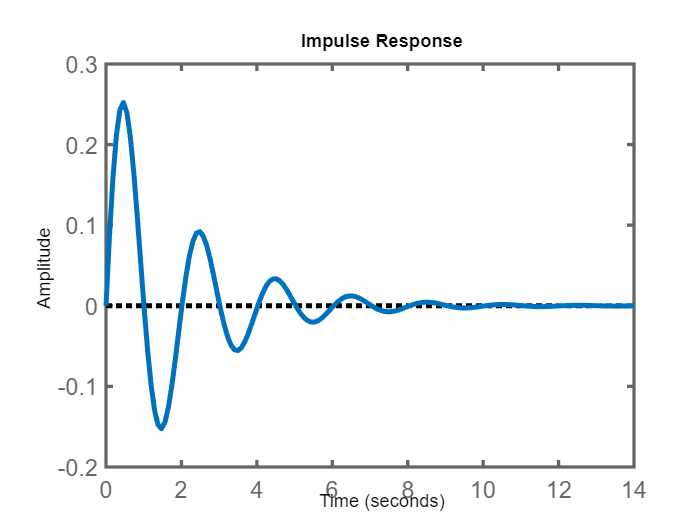


N     = 1;          % numerador
b     = 1;          % ?: atenuação
c     = 10;         % ?: oscilação
D     = [1 b c];    % denominador

Gs    = tf(N,D);    % função de transferência estimada

%%% visualizar

figure(2)

c = [0:1:10];

for k = 1 : length(c)

  D     = [1 b c(k)];    % denominador
  Gs    = tf(N,D);    % função de transferência estimada
  
  impulse(Gs);
  
end

%%% modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

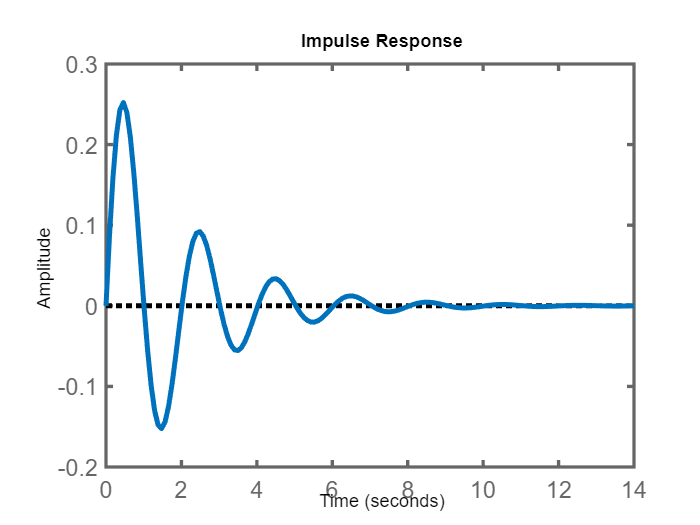


%%% Resposta do sistema no domínio do tempo

figure(3)

[serie,tempo,X] = impulse(Gs);
impulse(Gs)

%%% Modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

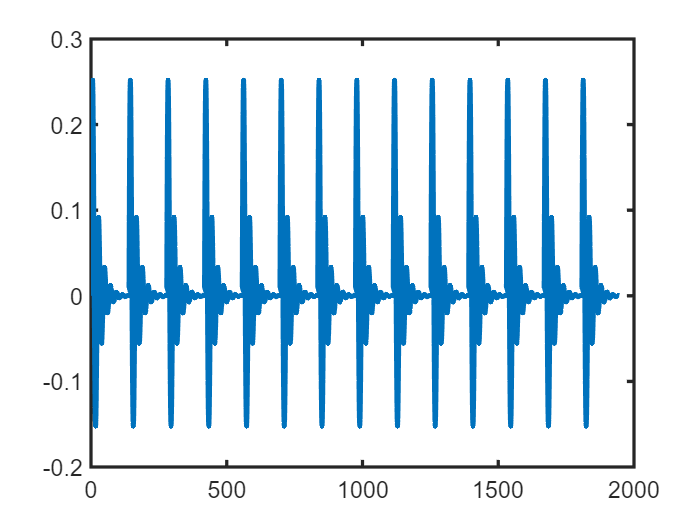


%%% Criando artificialmente a vogal

serie            = serie';
vogal_artificial = [serie serie serie serie serie serie serie];
vogal_artificial = [vogal_artificial vogal_artificial];
figure(4)
plot(vogal_artificial)
%%% Modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% b. Plot sobreposto da vogal com a resposta de Laplace. (2.0 pontos) 
%% 
%%  
figure(5)
plot(Vp,'LineWidth',2), title('Comparação de gt(t) e somatória das projeções p(t)');
hold;

Current plot held


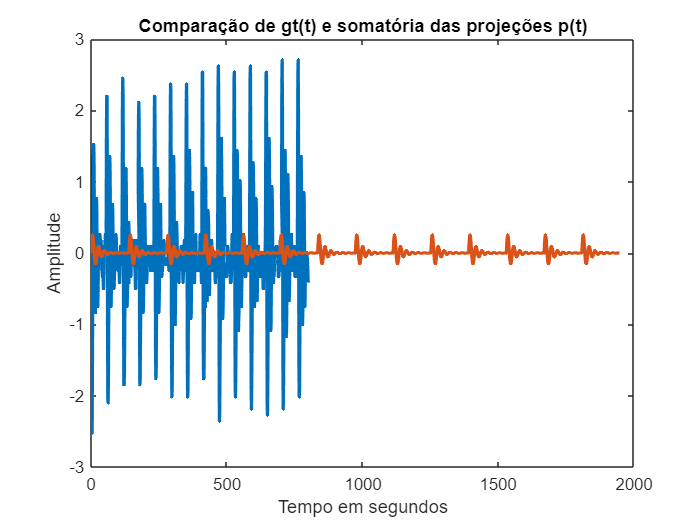

plot(vogal_artificial,'LineWidth',2),xlabel("Tempo em segundos"),ylabel("Amplitude")

%%% A série temporal representada em Laplace
N  =  13077;

D  = [1 1150 2.137e7];
Gvogal = tf(N,D);

%%% s = sigma + jw --> sigma < 0 --> decrescente

%%% Comparação com Fourier: sigma = 0 e analisar o jw


%%% Criando a função de Fourier 

GFourier = @(w) 1.308e+04./((j*w).^2 + 1150*(j*w) + 2.137e+07)

GFourier = function_handle with value:
    @(w)1.308e+04./((j*w).^2+1150*(j*w)+2.137e+07)



%%% Comparar o Fourier da série temporal com o Fourier da função de transferência

figure(1)

plot(frequencia,Y0);
xlabel('Frequencia em Hz');
ylabel('ganho em log10');
title('Comparacao entre Fourier e Laplace');
hold;

Current plot held


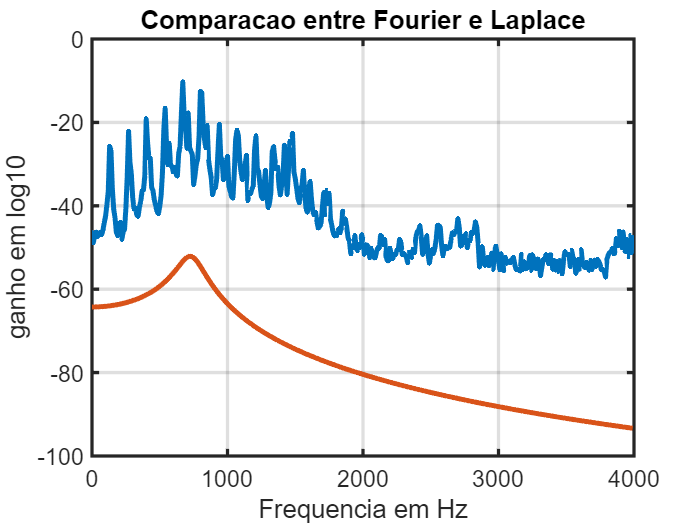

plot(frequencia, 20*log10(abs(GFourier(2*pi*frequencia))))
grid;

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);


%%% Relação da série temporal com os polos

Ns    = length(frequencia)

Ns = 400

sigma = linspace(-1000,0,Ns);
w     = 2*pi*frequencia;

GLaplace = @(s) 1.308e+04./((s).^2 + 1150*(s) + 2.137e+07)

GLaplace = function_handle with value:
    @(s)1.308e+04./((s).^2+1150*(s)+2.137e+07)


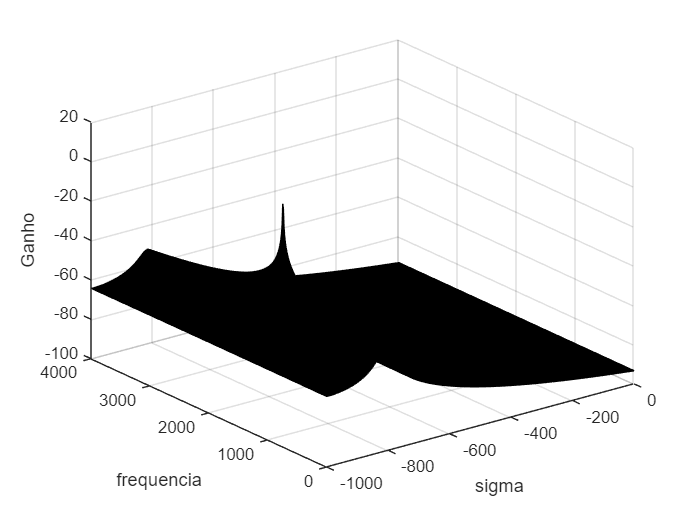


for m = 1: Ns
  x = sigma(m);
  for n = 1: Ns
    s = x + j*w(n);
    Ganho(m,n) = abs(GLaplace(s));
  end
end
  
  %%% Visualizar o resultado
  
  
  figure(2)
  surf(sigma,frequencia,20*log10(abs(Ganho)))
  xlabel('sigma')
  ylabel('frequencia')
  zlabel('Ganho')